## Collect file paths to the data files

The output of *getFileNames* is a string array containing the required file paths.

LGWFiles = getFileNames("Processed Data\IMU Data for assignment\LGW");
RAFiles = getFileNames("Processed Data\IMU Data for assignment\Ramp ascend");
RDFiles = getFileNames("Processed Data\IMU Data for assignment\Ramp descend");
SiStFiles = getFileNames("Processed Data\IMU Data for assignment\Sit to stand");
StSiFiles = getFileNames("Processed Data\IMU Data for assignment\Stand to sit");

## Read and collect the data

*collectData* takes the list of file paths given by *getFileNames* as input and outputs a struct of tables containing the data of all the files. The struct field name is the name of the file and the corresponding value contains the data from that file.

LGWRaw = collectData(LGWFiles);
RARaw = collectData(RAFiles);
RDRaw = collectData(RDFiles);
SiStRaw = collectData(SiStFiles);
StSiRaw = collectData(StSiFiles);
clearvars LGWFiles RAFiles RDFiles SiStFiles StSiFiles

## Check unnecessary extra columns

% Check column count
printColCount(LGWRaw)

normal_walk_J_trial_01 has 72 columns.
normal_walk_J_trial_02 has 72 columns.
normal_walk_J_trial_03 has 72 columns.
normal_walk_SV_trial_01 has 78 columns.
normal_walk_SV_trial_02 has 78 columns.
normal_walk_SV_trial_03 has 78 columns.
normal_walk_lg_trial_01 has 74 columns.
normal_walk_lg_trial_02 has 74 columns.
normal_walk_lg_trial_03 has 74 columns.
normal_walk_vr_trial_01 has 74 columns.
normal_walk_vr_trial_02 has 74 columns.
normal_walk_vr_trial_03 has 74 columns.


printColCount(RARaw)

ramp_asc_vr_trial_03 has 74 columns.
ramp_asc_j_trial_01 has 74 columns.
ramp_asc_j_trial_02 has 74 columns.
ramp_asc_j_trial_03 has 74 columns.
ramp_asc_lg_trial_01 has 74 columns.
ramp_asc_lg_trial_02 has 74 columns.
ramp_asc_lg_trial_03 has 74 columns.
ramp_asc_rs_trial_01 has 74 columns.
ramp_asc_rs_trial_02 has 74 columns.
ramp_asc_rs_trial_03 has 74 columns.
ramp_asc_vr_trial_01 has 74 columns.
ramp_asc_vr_trial_02 has 74 columns.


printColCount(RDRaw)

ramp_desc_jun_trial_01 has 74 columns.
ramp_desc_jun_trial_02 has 74 columns.
ramp_desc_jun_trial_03 has 74 columns.
ramp_desc_lg_trial_01 has 74 columns.
ramp_desc_lg_trial_02 has 74 columns.
ramp_desc_lg_trial_03 has 74 columns.
ramp_desc_rs_trial_01 has 74 columns.
ramp_desc_rs_trial_02 has 74 columns.
ramp_desc_rs_trial_03 has 74 columns.
ramp_desc_vr_trial_01 has 74 columns.
ramp_desc_vr_trial_02 has 74 columns.
ramp_desc_vr_trial_03 has 74 columns.


printColCount(SiStRaw)

sit_to_stand_jun_trial_01 has 74 columns.
sit_to_stand_jun_trial_02 has 74 columns.
sit_to_stand_jun_trial_03 has 74 columns.
sit_to_stand_lg_trial_01 has 74 columns.
sit_to_stand_lg_trial_02 has 74 columns.
sit_to_stand_lg_trial_03 has 74 columns.
sit_to_stand_rs_trial_01 has 74 columns.
sit_to_stand_rs_trial_02 has 74 columns.
sit_to_stand_rs_trial_03 has 74 columns.
sit_to_stand_vr_trial_01 has 74 columns.
sit_to_stand_vr_trial_02 has 74 columns.
sit_to_stand_vr_trial_03 has 74 columns.


printColCount(StSiRaw)

Students_stand_to_sit_lg_trial_01 has 74 columns.
Students_stand_to_sit_lg_trial_02 has 74 columns.
Students_stand_to_sit_lg_trial_03 has 74 columns.
Students_stand_to_sit_vr_trial_01 has 74 columns.
Students_stand_to_sit_vr_trial_02 has 74 columns.
Students_stand_to_sit_vr_trial_03 has 74 columns.
stand_to_sit_j_trial_01 has 74 columns.
stand_to_sit_j_trial_02 has 74 columns.
stand_to_sit_j_trial_03 has 74 columns.
stand_to_sit_rs_trial_01 has 74 columns.
stand_to_sit_rs_trial_02 has 74 columns.
stand_to_sit_rs_trial_03 has 74 columns.



% Check extra columns
printExtraCols(LGWRaw)

Extra column names (4 exist) in normal_walk_J_trial_01 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (4 exist) in normal_walk_J_trial_02 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (4 exist) in normal_walk_J_trial_03 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (10 exist) in normal_walk_SV_trial_01 are:
Foot_L_Offset_Timestamp, Foot_L_Sync_Timestamp, Foot_R_Sync_Timestamp, Pelvis_Offset_Timestamp, Pelvis_Sync_Timestamp, Shank_L_Offset_Timestamp, Shank_L_Sync_Timestamp, Shank_R_Sync_Timestamp, Thigh_L_Sync_Timestamp, Thigh_R_Sync_Timestamp, 

Extra column names (10 exist) in normal_walk_SV_trial_02 are:
Foot_L_Offset_Timestamp, Foot_L_Sync_Timestamp, Foot_R_Sync_Timestamp, Pelvis_Offset_Timestamp, Pelvis_Sync_Timestamp, Shank_L_Offset_Timestamp, Shank_L_Sync_Timestamp, Shank_R_Sync_Timestamp, Thigh_L_Sync_Timestamp, Thigh

printExtraCols(RARaw)

Extra column names (0 exist) in ramp_asc_vr_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_02 are:
, 



printExtraCols(RDRaw)

Extra column names (0 exist) in ramp_desc_jun_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_03 are:
, 



printExtraCols(SiStRaw)

Extra column names (0 exist) in sit_to_stand_jun_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_03 are:
, 



printExtraCols(StSiRaw)

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_03 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_03 are:
, 



**There are missing timestamp columns in the SV datasets for LGW**

**Assume the values with missing timestamp columns are already aligned**

### **We have been instructed to leave out all extra columns and all but one timestamp column and just assume that the timestamps for different sensors align.**

*more appropriate to match timestamps of different sensors

## Remove all timestamp columns except the first one and remove annotation columns

LGWCleaned = cleanAllTables(LGWRaw);
RACleaned = cleanAllTables(RARaw);
RDCleaned = cleanAllTables(RDRaw);
SiStCleaned = cleanAllTables(SiStRaw);
StSiCleaned = cleanAllTables(StSiRaw);
clearvars LGWRaw RARaw RDRaw SiStRaw StSiRaw

## Re-check extra columns

printExtraCols(LGWCleaned)

Extra column names (0 exist) in normal_walk_J_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_J_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_J_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_03 are:
, 



printExtraCols(RACleaned)

Extra column names (0 exist) in ramp_asc_vr_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_02 are:
, 



printExtraCols(RDCleaned)

Extra column names (0 exist) in ramp_desc_jun_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_03 are:
, 



printExtraCols(SiStCleaned)

Extra column names (0 exist) in sit_to_stand_jun_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_03 are:
, 



printExtraCols(StSiCleaned)

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_03 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_03 are:
, 



## Check for NaNs

checkForNan(LGWCleaned);

normal_walk_J_trial_01 has 0 NaNs.
normal_walk_J_trial_02 has 0 NaNs.
normal_walk_J_trial_03 has 0 NaNs.
normal_walk_SV_trial_01 has 0 NaNs.
normal_walk_SV_trial_02 has 0 NaNs.
normal_walk_SV_trial_03 has 0 NaNs.
normal_walk_lg_trial_01 has 584 NaNs.
normal_walk_lg_trial_02 has 584 NaNs.
normal_walk_lg_trial_03 has 0 NaNs.
normal_walk_vr_trial_01 has 0 NaNs.
normal_walk_vr_trial_02 has 0 NaNs.
normal_walk_vr_trial_03 has 0 NaNs.


checkForNan(RACleaned);

ramp_asc_vr_trial_03 has 0 NaNs.
ramp_asc_j_trial_01 has 0 NaNs.
ramp_asc_j_trial_02 has 0 NaNs.
ramp_asc_j_trial_03 has 0 NaNs.
ramp_asc_lg_trial_01 has 0 NaNs.
ramp_asc_lg_trial_02 has 0 NaNs.
ramp_asc_lg_trial_03 has 0 NaNs.
ramp_asc_rs_trial_01 has 0 NaNs.
ramp_asc_rs_trial_02 has 0 NaNs.
ramp_asc_rs_trial_03 has 0 NaNs.
ramp_asc_vr_trial_01 has 0 NaNs.
ramp_asc_vr_trial_02 has 0 NaNs.


checkForNan(RDCleaned);

ramp_desc_jun_trial_01 has 0 NaNs.
ramp_desc_jun_trial_02 has 0 NaNs.
ramp_desc_jun_trial_03 has 0 NaNs.
ramp_desc_lg_trial_01 has 0 NaNs.
ramp_desc_lg_trial_02 has 0 NaNs.
ramp_desc_lg_trial_03 has 0 NaNs.
ramp_desc_rs_trial_01 has 0 NaNs.
ramp_desc_rs_trial_02 has 0 NaNs.
ramp_desc_rs_trial_03 has 0 NaNs.
ramp_desc_vr_trial_01 has 0 NaNs.
ramp_desc_vr_trial_02 has 0 NaNs.
ramp_desc_vr_trial_03 has 0 NaNs.


checkForNan(SiStCleaned);

sit_to_stand_jun_trial_01 has 0 NaNs.
sit_to_stand_jun_trial_02 has 0 NaNs.
sit_to_stand_jun_trial_03 has 0 NaNs.
sit_to_stand_lg_trial_01 has 0 NaNs.
sit_to_stand_lg_trial_02 has 0 NaNs.
sit_to_stand_lg_trial_03 has 0 NaNs.
sit_to_stand_rs_trial_01 has 0 NaNs.
sit_to_stand_rs_trial_02 has 0 NaNs.
sit_to_stand_rs_trial_03 has 0 NaNs.
sit_to_stand_vr_trial_01 has 0 NaNs.
sit_to_stand_vr_trial_02 has 0 NaNs.
sit_to_stand_vr_trial_03 has 0 NaNs.


checkForNan(StSiCleaned);

Students_stand_to_sit_lg_trial_01 has 0 NaNs.
Students_stand_to_sit_lg_trial_02 has 0 NaNs.
Students_stand_to_sit_lg_trial_03 has 0 NaNs.
Students_stand_to_sit_vr_trial_01 has 0 NaNs.
Students_stand_to_sit_vr_trial_02 has 0 NaNs.
Students_stand_to_sit_vr_trial_03 has 0 NaNs.
stand_to_sit_j_trial_01 has 0 NaNs.
stand_to_sit_j_trial_02 has 0 NaNs.
stand_to_sit_j_trial_03 has 0 NaNs.
stand_to_sit_rs_trial_01 has 0 NaNs.
stand_to_sit_rs_trial_02 has 0 NaNs.
stand_to_sit_rs_trial_03 has 0 NaNs.


## Interpolate NaNs

LGWCleaned = interpolateAll(LGWCleaned);
RACleaned = interpolateAll(RACleaned);
RDCleaned = interpolateAll(RDCleaned);
SiStCleaned = interpolateAll(SiStCleaned);
StSiCleaned = interpolateAll(StSiCleaned);

## Re-check for NaNs

checkForNan(LGWCleaned);

normal_walk_J_trial_01 has 0 NaNs.
normal_walk_J_trial_02 has 0 NaNs.
normal_walk_J_trial_03 has 0 NaNs.
normal_walk_SV_trial_01 has 0 NaNs.
normal_walk_SV_trial_02 has 0 NaNs.
normal_walk_SV_trial_03 has 0 NaNs.
normal_walk_lg_trial_01 has 0 NaNs.
normal_walk_lg_trial_02 has 0 NaNs.
normal_walk_lg_trial_03 has 0 NaNs.
normal_walk_vr_trial_01 has 0 NaNs.
normal_walk_vr_trial_02 has 0 NaNs.
normal_walk_vr_trial_03 has 0 NaNs.


checkForNan(RACleaned);

ramp_asc_vr_trial_03 has 0 NaNs.
ramp_asc_j_trial_01 has 0 NaNs.
ramp_asc_j_trial_02 has 0 NaNs.
ramp_asc_j_trial_03 has 0 NaNs.
ramp_asc_lg_trial_01 has 0 NaNs.
ramp_asc_lg_trial_02 has 0 NaNs.
ramp_asc_lg_trial_03 has 0 NaNs.
ramp_asc_rs_trial_01 has 0 NaNs.
ramp_asc_rs_trial_02 has 0 NaNs.
ramp_asc_rs_trial_03 has 0 NaNs.
ramp_asc_vr_trial_01 has 0 NaNs.
ramp_asc_vr_trial_02 has 0 NaNs.


checkForNan(RDCleaned);

ramp_desc_jun_trial_01 has 0 NaNs.
ramp_desc_jun_trial_02 has 0 NaNs.
ramp_desc_jun_trial_03 has 0 NaNs.
ramp_desc_lg_trial_01 has 0 NaNs.
ramp_desc_lg_trial_02 has 0 NaNs.
ramp_desc_lg_trial_03 has 0 NaNs.
ramp_desc_rs_trial_01 has 0 NaNs.
ramp_desc_rs_trial_02 has 0 NaNs.
ramp_desc_rs_trial_03 has 0 NaNs.
ramp_desc_vr_trial_01 has 0 NaNs.
ramp_desc_vr_trial_02 has 0 NaNs.
ramp_desc_vr_trial_03 has 0 NaNs.


checkForNan(SiStCleaned);

sit_to_stand_jun_trial_01 has 0 NaNs.
sit_to_stand_jun_trial_02 has 0 NaNs.
sit_to_stand_jun_trial_03 has 0 NaNs.
sit_to_stand_lg_trial_01 has 0 NaNs.
sit_to_stand_lg_trial_02 has 0 NaNs.
sit_to_stand_lg_trial_03 has 0 NaNs.
sit_to_stand_rs_trial_01 has 0 NaNs.
sit_to_stand_rs_trial_02 has 0 NaNs.
sit_to_stand_rs_trial_03 has 0 NaNs.
sit_to_stand_vr_trial_01 has 0 NaNs.
sit_to_stand_vr_trial_02 has 0 NaNs.
sit_to_stand_vr_trial_03 has 0 NaNs.


checkForNan(StSiCleaned);

Students_stand_to_sit_lg_trial_01 has 0 NaNs.
Students_stand_to_sit_lg_trial_02 has 0 NaNs.
Students_stand_to_sit_lg_trial_03 has 0 NaNs.
Students_stand_to_sit_vr_trial_01 has 0 NaNs.
Students_stand_to_sit_vr_trial_02 has 0 NaNs.
Students_stand_to_sit_vr_trial_03 has 0 NaNs.
stand_to_sit_j_trial_01 has 0 NaNs.
stand_to_sit_j_trial_02 has 0 NaNs.
stand_to_sit_j_trial_03 has 0 NaNs.
stand_to_sit_rs_trial_01 has 0 NaNs.
stand_to_sit_rs_trial_02 has 0 NaNs.
stand_to_sit_rs_trial_03 has 0 NaNs.


## Check row counts

printRowCount(LGWCleaned)

normal_walk_J_trial_01 has 1610 rows.
normal_walk_J_trial_02 has 1626 rows.
normal_walk_J_trial_03 has 1489 rows.
normal_walk_SV_trial_01 has 1682 rows.
normal_walk_SV_trial_02 has 1682 rows.
normal_walk_SV_trial_03 has 1603 rows.
normal_walk_lg_trial_01 has 1521 rows.
normal_walk_lg_trial_02 has 1521 rows.
normal_walk_lg_trial_03 has 1426 rows.
normal_walk_vr_trial_01 has 1568 rows.
normal_walk_vr_trial_02 has 1554 rows.
normal_walk_vr_trial_03 has 1905 rows.


printRowCount(RACleaned)

ramp_asc_vr_trial_03 has 753 rows.
ramp_asc_j_trial_01 has 696 rows.
ramp_asc_j_trial_02 has 692 rows.
ramp_asc_j_trial_03 has 727 rows.
ramp_asc_lg_trial_01 has 966 rows.
ramp_asc_lg_trial_02 has 796 rows.
ramp_asc_lg_trial_03 has 753 rows.
ramp_asc_rs_trial_01 has 593 rows.
ramp_asc_rs_trial_02 has 878 rows.
ramp_asc_rs_trial_03 has 840 rows.
ramp_asc_vr_trial_01 has 952 rows.
ramp_asc_vr_trial_02 has 860 rows.


printRowCount(RDCleaned)

ramp_desc_jun_trial_01 has 705 rows.
ramp_desc_jun_trial_02 has 603 rows.
ramp_desc_jun_trial_03 has 610 rows.
ramp_desc_lg_trial_01 has 745 rows.
ramp_desc_lg_trial_02 has 829 rows.
ramp_desc_lg_trial_03 has 715 rows.
ramp_desc_rs_trial_01 has 752 rows.
ramp_desc_rs_trial_02 has 944 rows.
ramp_desc_rs_trial_03 has 788 rows.
ramp_desc_vr_trial_01 has 923 rows.
ramp_desc_vr_trial_02 has 814 rows.
ramp_desc_vr_trial_03 has 796 rows.


printRowCount(SiStCleaned)

sit_to_stand_jun_trial_01 has 389 rows.
sit_to_stand_jun_trial_02 has 412 rows.
sit_to_stand_jun_trial_03 has 359 rows.
sit_to_stand_lg_trial_01 has 579 rows.
sit_to_stand_lg_trial_02 has 662 rows.
sit_to_stand_lg_trial_03 has 720 rows.
sit_to_stand_rs_trial_01 has 338 rows.
sit_to_stand_rs_trial_02 has 458 rows.
sit_to_stand_rs_trial_03 has 321 rows.
sit_to_stand_vr_trial_01 has 537 rows.
sit_to_stand_vr_trial_02 has 508 rows.
sit_to_stand_vr_trial_03 has 632 rows.


printRowCount(StSiCleaned)

Students_stand_to_sit_lg_trial_01 has 539 rows.
Students_stand_to_sit_lg_trial_02 has 545 rows.
Students_stand_to_sit_lg_trial_03 has 661 rows.
Students_stand_to_sit_vr_trial_01 has 462 rows.
Students_stand_to_sit_vr_trial_02 has 551 rows.
Students_stand_to_sit_vr_trial_03 has 554 rows.
stand_to_sit_j_trial_01 has 345 rows.
stand_to_sit_j_trial_02 has 362 rows.
stand_to_sit_j_trial_03 has 316 rows.
stand_to_sit_rs_trial_01 has 359 rows.
stand_to_sit_rs_trial_02 has 362 rows.
stand_to_sit_rs_trial_03 has 281 rows.


LGW seems to have much more rows as compared to the other categories. This may introduce bias.

## Apply Low Pass Filter

LGWFiltered = lowPassAll(LGWCleaned);
RAFiltered = lowPassAll(RACleaned);
RDFiltered = lowPassAll(RDCleaned);
SiStFiltered = lowPassAll(SiStCleaned);
StSiFiltered = lowPassAll(StSiCleaned);

## Moving statistical values

% Window size
tw = 400;
% Increment
dt = 70/1000;

Moving mean

LGWProcessed = generateFeaturesForAllTables(LGWFiltered, tw, dt);
RAProcessed = generateFeaturesForAllTables(RAFiltered, tw, dt);
RDProcessed = generateFeaturesForAllTables(RDFiltered, tw, dt);
SiStProcessed = generateFeaturesForAllTables(SiStFiltered, tw, dt);
StSiProcessed = generateFeaturesForAllTables(StSiFiltered, tw, dt);

## Add one-hot encoded columns and combine the 5 categories into one dataset

statisticalDataset = combineAndAddOneHot(LGWProcessed, RAProcessed, RDProcessed, SiStProcessed, StSiProcessed);

Merged:
2062 rows from LGW
677 rows from RA
640 rows from RD
191 rows from SiSt
133 rows from StSi


featX = table2array(statisticalDataset(:, 1:end-5));
featY = table2array(statisticalDataset(:, end-4:end));
size(featX)

ans =         3703         441


size(featY)

ans =         3703           5


## Generate dataset for CNN

[cnnX, cnnY] = generateCNNDataset(LGWFiltered, RAFiltered, RDFiltered, SiStFiltered, StSiFiltered, tw, dt);

Generating windows of size (400, 63)


size(cnnX)

ans =          400          63           1        3703


size(cnnY)

ans =            1        3703


## 1. Classification error for the used features

### ANN

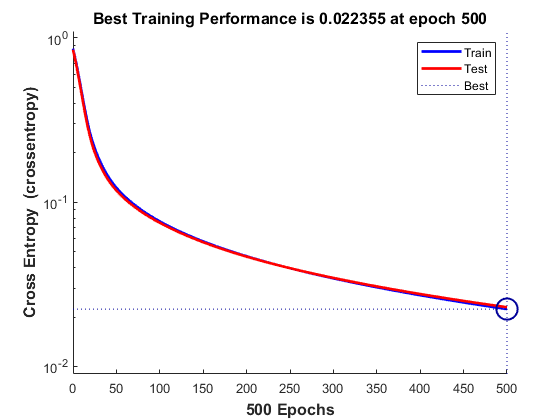

rng(1)
% Create a Pattern Recognition Network
net = patternnet(25, 'traingdm');

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 20/100;

net.trainParam.epochs = 500;

X = featX';
Y = featY';

% Train the Network
[net, tr] = train(net, X, Y);
plotperform(tr)

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(X(:,tInd));
[c,~] = confusion(Y(:,tInd),tstOutputs);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.014845

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 98.515520%

plotconfusion(Y(:,tInd),tstOutputs)

### SVM

% SVM parameters
t = templateSVM('Standardize',true,'SaveSupportVectors',true);

% Convert Y from one-hot to categorical
featYcat = categorical(featY(:,1) + featY(:,2) * 2 + featY(:,3) * 3 + featY(:,4) * 4 + featY(:,5) * 5);

% Train the SVM
svm = fitcecoc(featX, featYcat, 'Holdout', 0.20, 'Learners', t);

%extract the trained model
mdl = svm.Trained{1};

tInd = test(svm.Partition);
tstOutputs = predict(mdl,featX(tInd,:));
tstOutputsOneHot = onehotencode(tstOutputs, 2);
[c,~] = confusion(featY(tInd,:)', tstOutputsOneHot');
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.000000

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 100.000000%

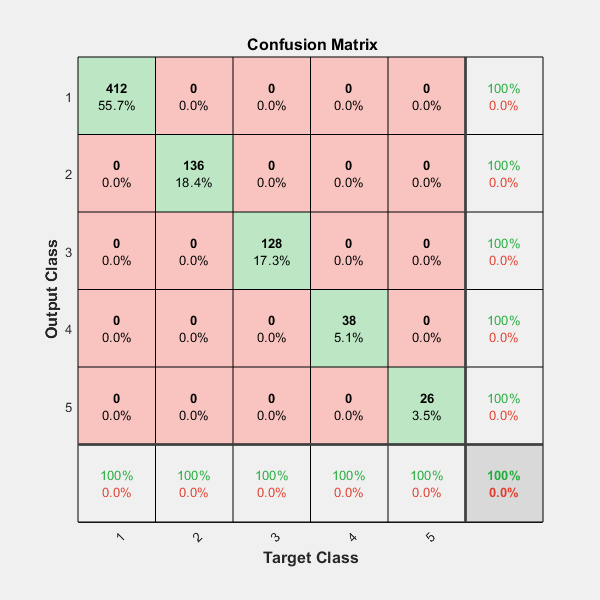

plotconfusion(featY(tInd,:)', tstOutputsOneHot')

### CNN

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:11 |       11.33% |       2.1910 |          0.0100 |
|       5 |          50 |       00:00:27 |       92.19% |       0.1759 |          0.0100 |
|      10 |         100 |       00:00:47 |       97.66% |       0.1181 |          0.0100 |
|      14 |         150 |       00:01:09 |       96.88% |       0.1096 |          0.0100 |
|      19 |         200 |       00:01:31 |       97.27% |       0.1017 |          0.0100 |
|      23 |         250 |       00:01:52 |       98.44% |       0.0970 |          0.0100 |
|      25 |         275 |  

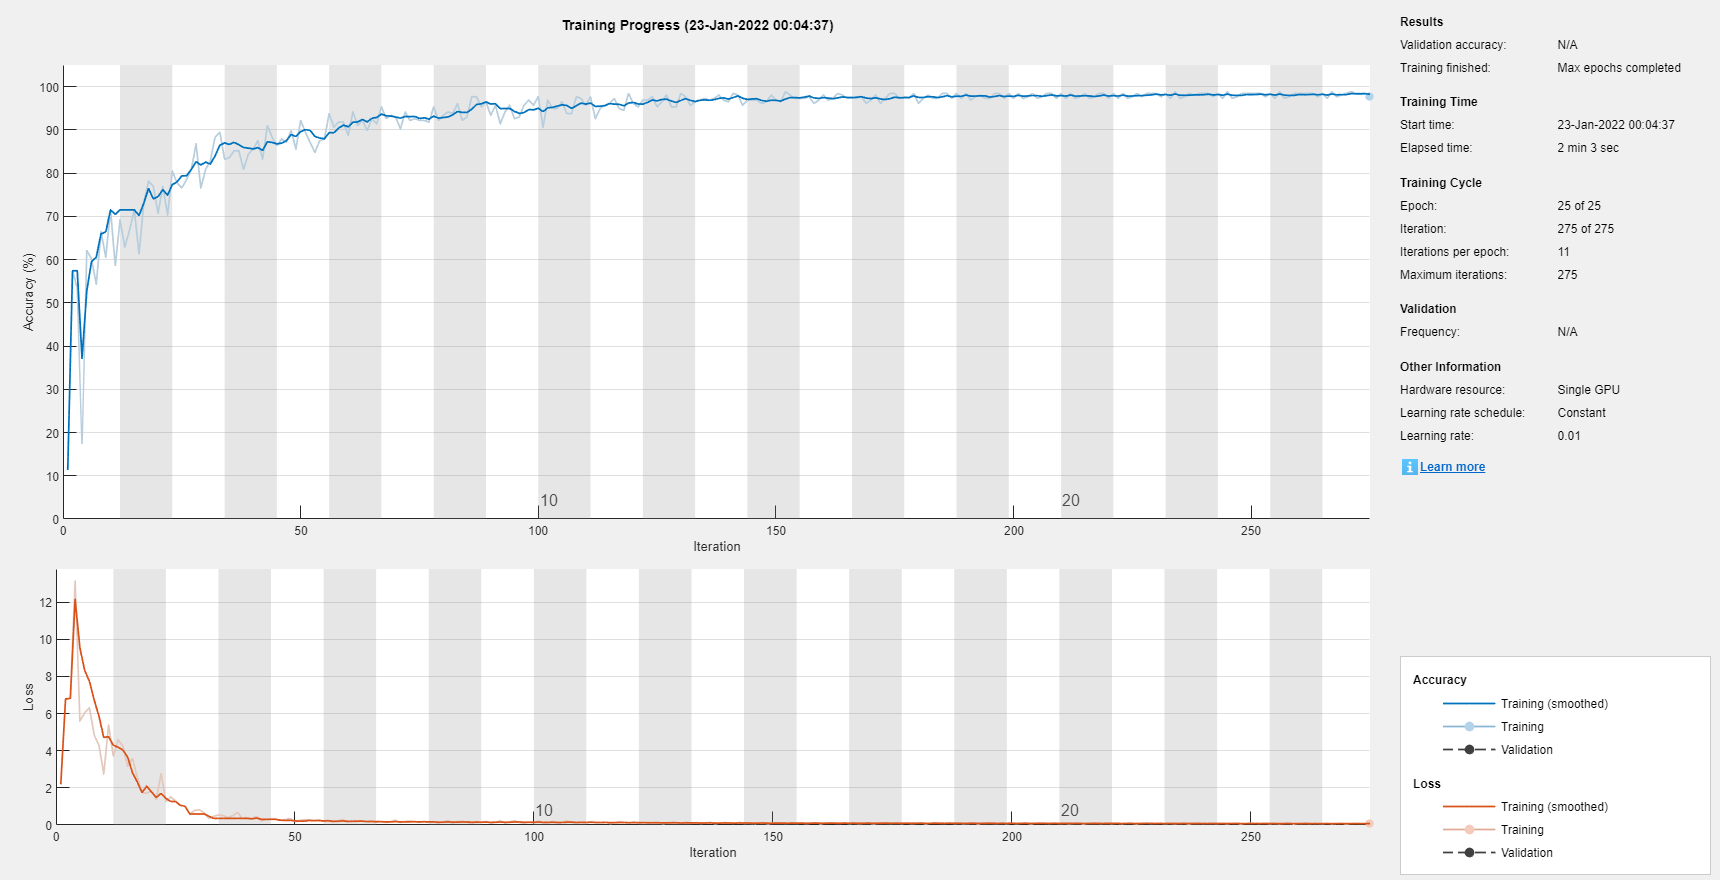

cnnLayers = createCNN(cnnX, cnnY);

options = trainingOptions( 'sgdm',...
    'MiniBatchSize', 256,...
    'MaxEpochs', 25,...
    'Plots', 'training-progress');

% Split train and test set
cv = cvpartition(size(cnnX,4), 'HoldOut', 0.2);
idx = cv.test;
cnnXtrain = cnnX(:,:,:,~idx);
cnnXtest = cnnX(:,:,:,idx);
cnnYtrain = cnnY(~idx);
cnnYtest = cnnY(idx);

% Train the model
net = trainNetwork(cnnXtrain, cnnYtrain, cnnLayers, options);

tstOutputs = (net.classify(cnnXtest))';
tstOutputsOneHot = onehotencode(tstOutputs, 1);
cnnYtestOneHot = onehotencode(cnnYtest, 1);
[c,~] = confusion(cnnYtestOneHot, tstOutputsOneHot);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.027027

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 97.297297%

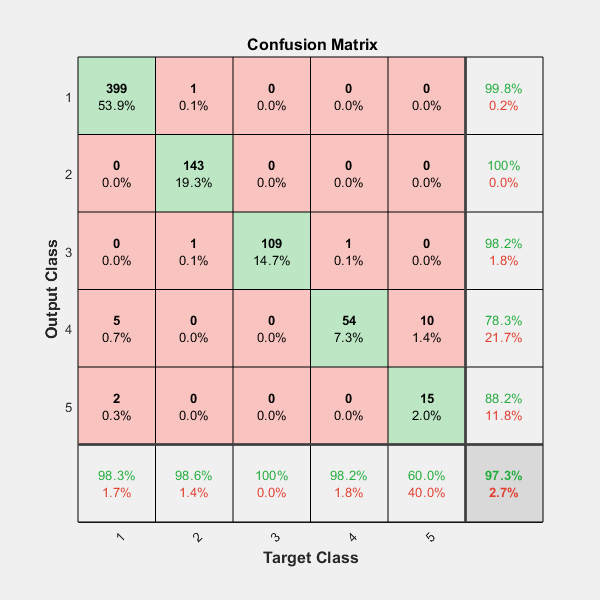

plotconfusion(cnnYtestOneHot, tstOutputsOneHot)

## 2. The most significant fifteen features

### Using Minimum Redundancy Maximum Relevance (MRMR) Algorithm

% Convert the target columns in statisticalDataset from one-hot to categorical
categoricalTarget = categorical(featY(:,1) + featY(:,2) * 2 + featY(:,3) * 3 + featY(:,4) * 4 + featY(:,5) * 5);
featDatasetCategorical = [statisticalDataset table(categoricalTarget, 'VariableNames', ["Target"])];
featDatasetCategorical.LGW = [];
featDatasetCategorical.RA = [];
featDatasetCategorical.RD = [];
featDatasetCategorical.SiSt = [];
featDatasetCategorical.StSi = [];

[idx, scores] = fscmrmr(featDatasetCategorical, "Target");

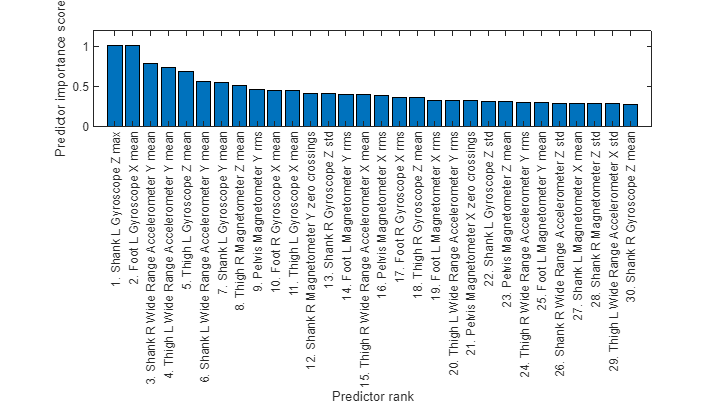

figure('Position', [50, 50, 800, 450])
bar(scores(idx(1:30)))
xlabel('Predictor rank')
xticks([1:30])
xticklabels([1:30]+". "+strrep(string(featDatasetCategorical.Properties.VariableNames(idx(1:30))), "_", " "))
xtickangle(90)
ylabel('Predictor importance score')

From the above figure, we can clearly see the fifteen most significant features. In fact it looks like the top 2 features are way more significant than most. These top two are gyroscope values, and that makes sense since most of our joint motion is rotational rather than translational.

#### Training ANN on only top 15 features

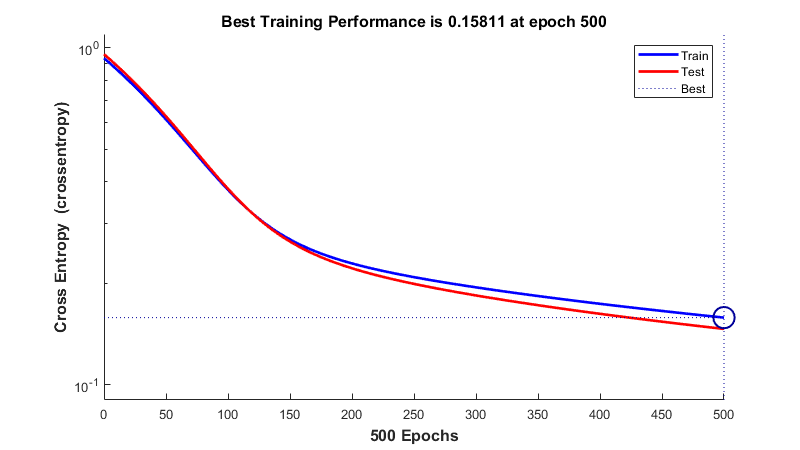

% Create a Pattern Recognition Network
net = patternnet(25, 'traingdm');

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 20/100;

net.trainParam.epochs = 500;

top15X = featX(:,idx(1:15))';
Y = featY';

% Train the Network
[net, tr] = train(net, top15X, Y);
plotperform(tr)

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(top15X(:,tInd));
[c,~] = confusion(Y(:,tInd),tstOutputs);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.276653

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 72.334683%

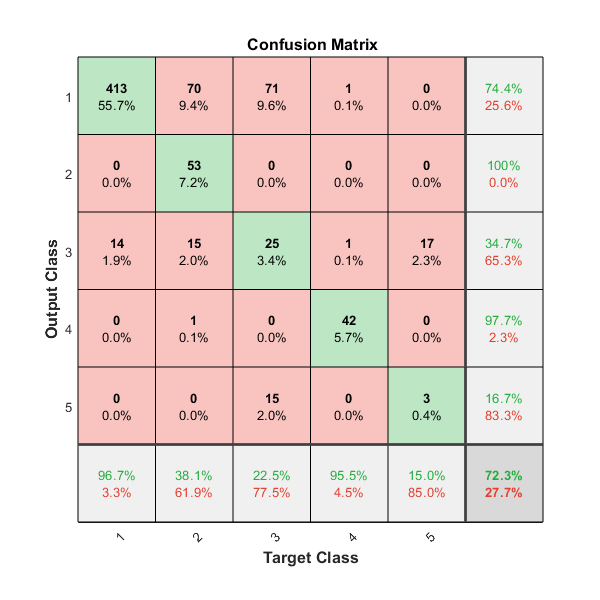

plotconfusion(Y(:,tInd),tstOutputs)

We see that the classification accuracy drops a lot with just 15 features.

#### Training ANN on only top 30 features

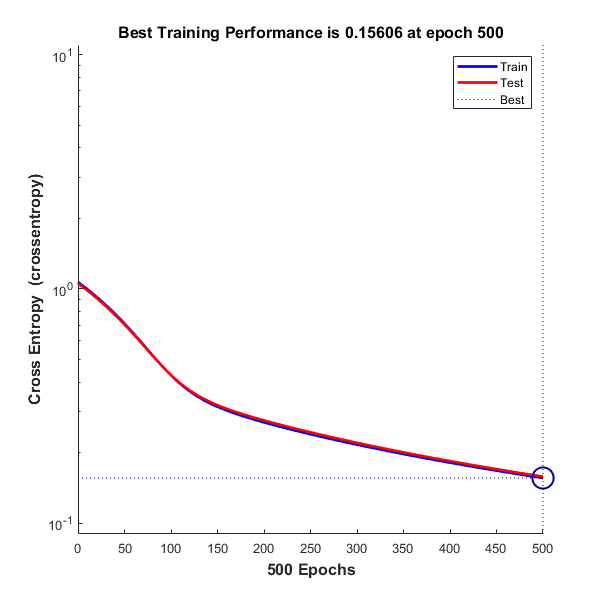

% Create a Pattern Recognition Network
net = patternnet(25, 'traingdm');

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 20/100;

net.trainParam.epochs = 500;

top15X = featX(:,idx(1:30))';
Y = featY';

% Train the Network
[net, tr] = train(net, top15X, Y);
plotperform(tr)

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(top15X(:,tInd));
[c,~] = confusion(Y(:,tInd),tstOutputs);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.334683

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 66.531714%

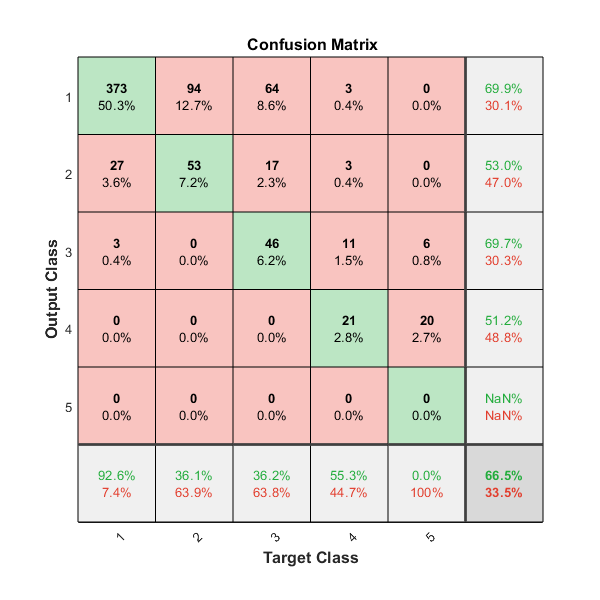

plotconfusion(Y(:,tInd),tstOutputs)

We see that the accuracy is much more acceptable with 30 features.

## 3. The most significant segment which contributes to the activities recognition

% Split dataset into different segments
varNames = string(statisticalDataset.Properties.VariableNames);

thighRX = table2array(statisticalDataset(:, startsWith(varNames, "Thigh_R")));
shankRX = table2array(statisticalDataset(:, startsWith(varNames, "Shank_R")));
footRX = table2array(statisticalDataset(:, startsWith(varNames, "Foot_R")));
thighLX = table2array(statisticalDataset(:, startsWith(varNames, "Thigh_L")));
shankLX = table2array(statisticalDataset(:, startsWith(varNames, "Shank_L")));
footLX = table2array(statisticalDataset(:, startsWith(varNames, "Foot_L")));
pelvisX = table2array(statisticalDataset(:, startsWith(varNames, "Pelvis")));

Mean classification error of test set from 10 trials: 0.174359
Mean classification accuracy of test set from 10 trials: 82.564103%
Std classification error of test set from 10 trials: 0.076732
Std classification accuracy of test set from 10 trials: 7.673159%


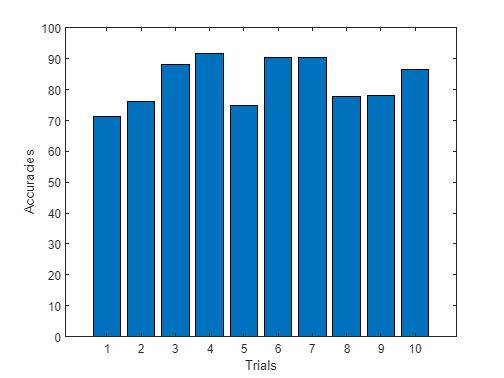

% Train each segment on the ANN and check accuracy
rng(1); % set rng seed for reproducibility
printAccuracy(thighRX', featY');

Mean classification error of test set from 10 trials: 0.134953
Mean classification accuracy of test set from 10 trials: 86.504723%
Std classification error of test set from 10 trials: 0.038566
Std classification accuracy of test set from 10 trials: 3.856597%


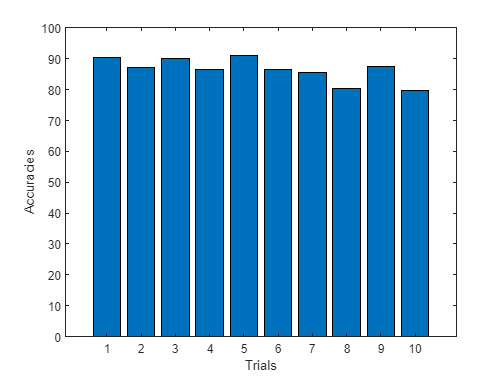

printAccuracy(shankRX', featY');

Mean classification error of test set from 10 trials: 0.188664
Mean classification accuracy of test set from 10 trials: 81.133603%
Std classification error of test set from 10 trials: 0.032834
Std classification accuracy of test set from 10 trials: 3.283419%


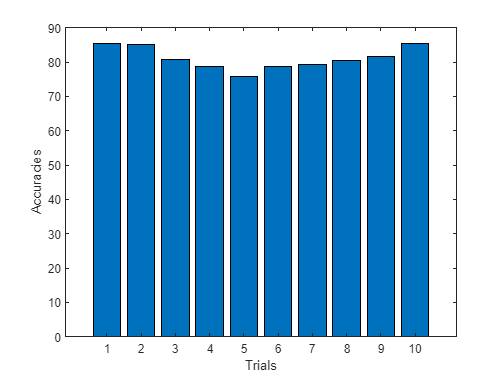

printAccuracy(footRX', featY');

Mean classification error of test set from 10 trials: 0.210931
Mean classification accuracy of test set from 10 trials: 78.906883%
Std classification error of test set from 10 trials: 0.043456
Std classification accuracy of test set from 10 trials: 4.345605%


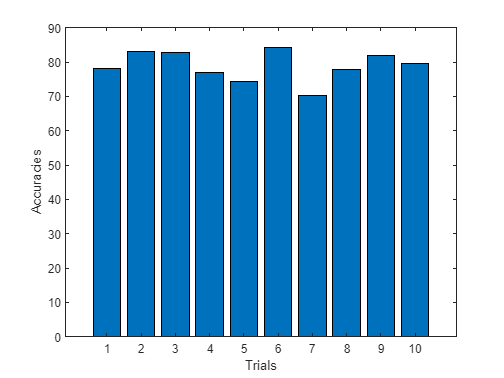

printAccuracy(thighLX', featY');

Mean classification error of test set from 10 trials: 0.178138
Mean classification accuracy of test set from 10 trials: 82.186235%
Std classification error of test set from 10 trials: 0.033349
Std classification accuracy of test set from 10 trials: 3.334908%


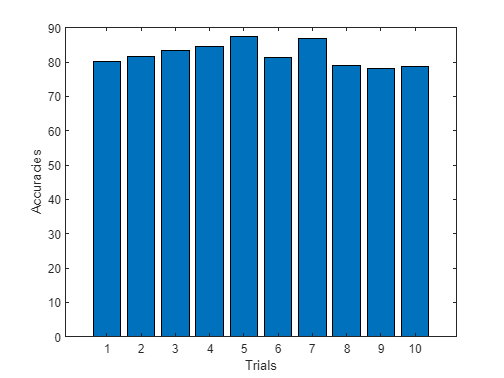

printAccuracy(shankLX', featY');

Mean classification error of test set from 10 trials: 0.167341
Mean classification accuracy of test set from 10 trials: 83.265857%
Std classification error of test set from 10 trials: 0.038450
Std classification accuracy of test set from 10 trials: 3.845036%


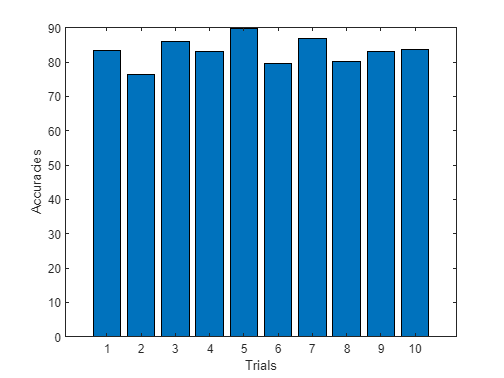

printAccuracy(footLX', featY');

Mean classification error of test set from 10 trials: 0.206883
Mean classification accuracy of test set from 10 trials: 79.311741%
Std classification error of test set from 10 trials: 0.055303
Std classification accuracy of test set from 10 trials: 5.530338%


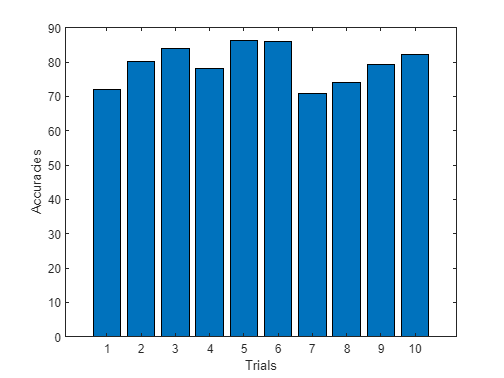

printAccuracy(pelvisX', featY');

While there is significant deviation in accuracies for some segments, overall, we can say that the shanks and feet sensors have a more steady contribution and hence can be considered important. The pelvis sensor's contribution to the accuracy shows high amount of variance and hence might not always be reliable.

From purely the means of the accuracies we can say that Shank_R is the most significant

## 4. Using only the features from the significant segment (identified in 3), find the classification error

### ANN

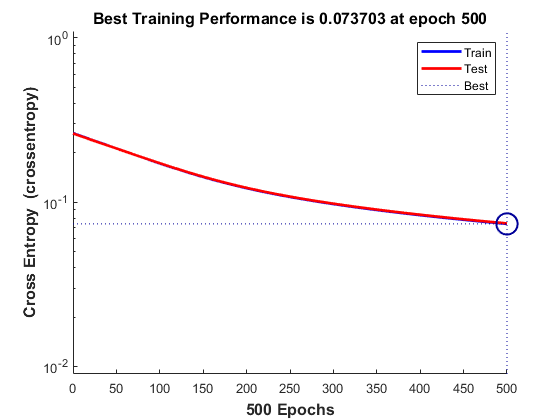

% Create a Pattern Recognition Network
net = patternnet(25, 'traingdm');

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 20/100;

net.trainParam.epochs = 500;

X = shankRX';
Y = featY';

% Train the Network
[net, tr] = train(net, X, Y);
plotperform(tr)

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(X(:,tInd));
[c,~] = confusion(Y(:,tInd),tstOutputs);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.098516

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 90.148448%

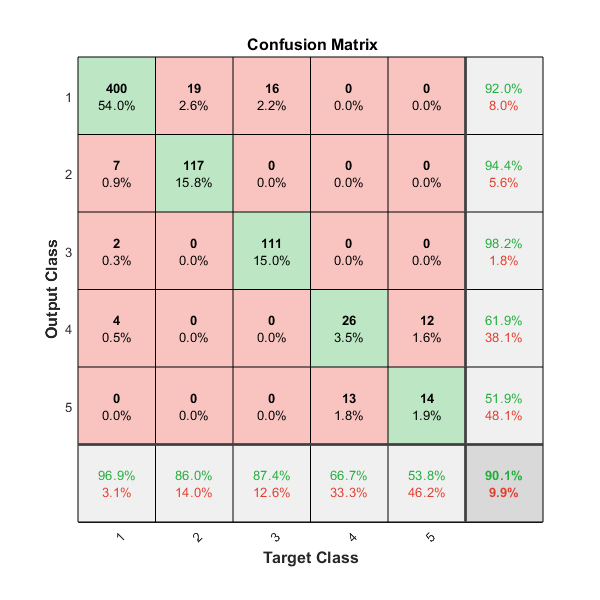

plotconfusion(Y(:,tInd),tstOutputs)

### SVM

% SVM parameters
t = templateSVM('Standardize',true,'SaveSupportVectors',true);

% Convert Y from one-hot to categorical
featYcat = categorical(featY(:,1) + featY(:,2) * 2 + featY(:,3) * 3 + featY(:,4) * 4 + featY(:,5) * 5);

% Train the SVM
svm = fitcecoc(shankRX, featYcat, 'Holdout', 0.20, 'Learners', t);

%extract the trained model
mdl = svm.Trained{1};

tInd = test(svm.Partition);
tstOutputs = predict(mdl,shankRX(tInd,:));
tstOutputsOneHot = onehotencode(tstOutputs, 2);
[c,~] = confusion(featY(tInd,:)', tstOutputsOneHot');
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.000000

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 100.000000%

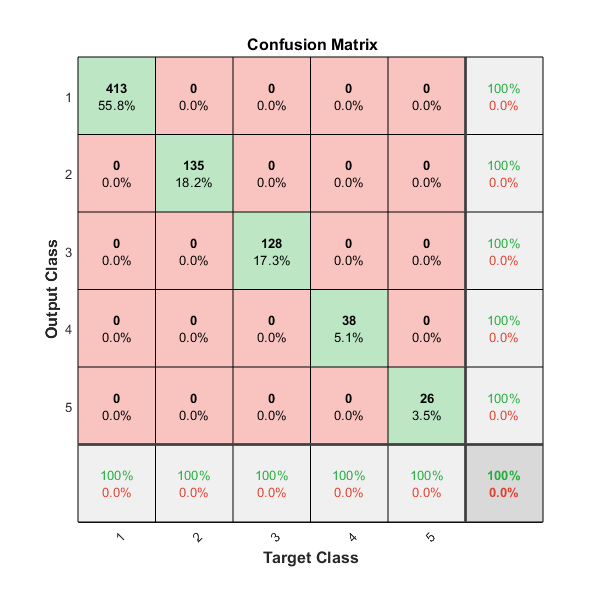

plotconfusion(featY(tInd,:)', tstOutputsOneHot')

### CNN

% Create CNN dataset with just Shank_R
LGWShankR = getOnlyColsStartWith(LGWFiltered, "Shank_R");
RAShankR = getOnlyColsStartWith(RAFiltered, "Shank_R");
RDShankR = getOnlyColsStartWith(RDFiltered, "Shank_R");
SiStShankR = getOnlyColsStartWith(SiStFiltered, "Shank_R");
StSiShankR = getOnlyColsStartWith(StSiFiltered, "Shank_R");
[cnnXShankR, cnnYShankR] = generateCNNDataset(LGWShankR, RAShankR, RDShankR, SiStShankR, StSiShankR, tw, dt);

Generating windows of size (400, 9)


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       21.88% |       1.8211 |          0.0100 |
|       5 |          50 |       00:00:06 |       85.16% |       0.3443 |          0.0100 |
|      10 |         100 |       00:00:09 |       95.31% |       0.1133 |          0.0100 |
|      14 |         150 |       00:00:12 |       92.19% |       0.1147 |          0.0100 |
|      19 |         200 |       00:00:15 |       94.53% |       0.0928 |          0.0100 |
|      23 |         250 |       00:00:18 |       98.83% |       0.0639 |          0.0100 |
|      25 |         275 |  

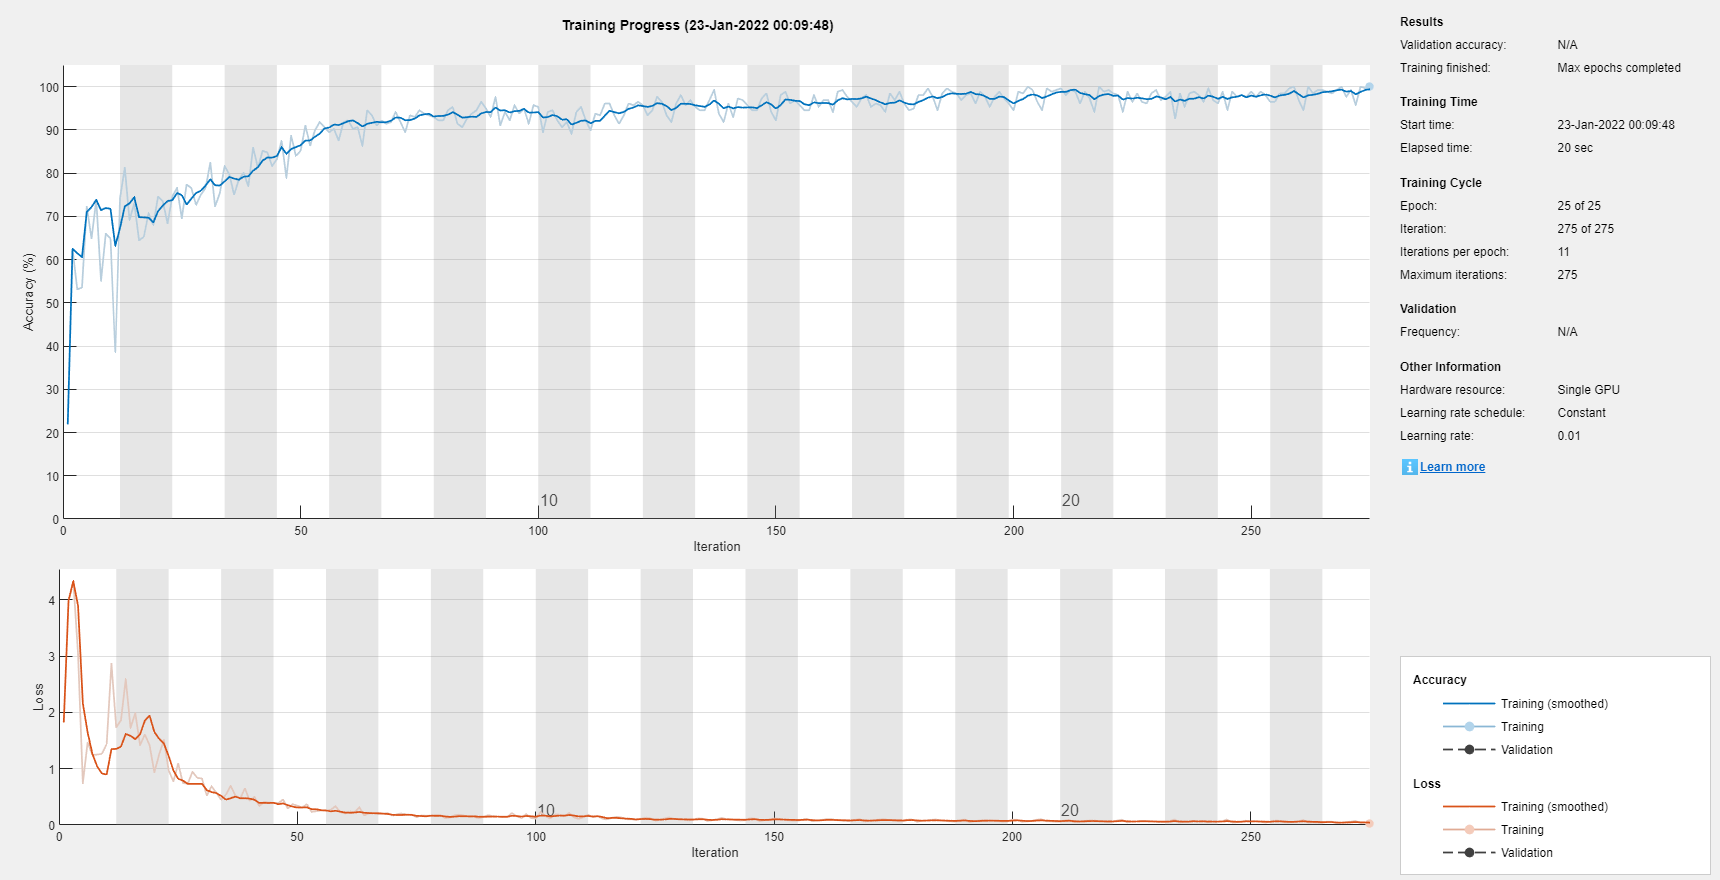


cnnLayers = createCNN(cnnXShankR, cnnYShankR);

options = trainingOptions( 'sgdm',...
    'MiniBatchSize', 256,...
    'MaxEpochs', 25,...
    'Plots', 'training-progress');

% Split train and test set
cv = cvpartition(size(cnnXShankR,4), 'HoldOut', 0.2);
idx = cv.test;
cnnXtrain = cnnXShankR(:,:,:,~idx);
cnnXtest = cnnXShankR(:,:,:,idx);
cnnYtrain = cnnYShankR(~idx);
cnnYtest = cnnYShankR(idx);

% Train the model
net = trainNetwork(cnnXtrain, cnnYtrain, cnnLayers, options);

tstOutputs = (net.classify(cnnXtest))';
tstOutputsOneHot = onehotencode(tstOutputs, 1);
cnnYtestOneHot = onehotencode(cnnYtest, 1);
[c,~] = confusion(cnnYtestOneHot, tstOutputsOneHot);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.008108

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 99.189189%

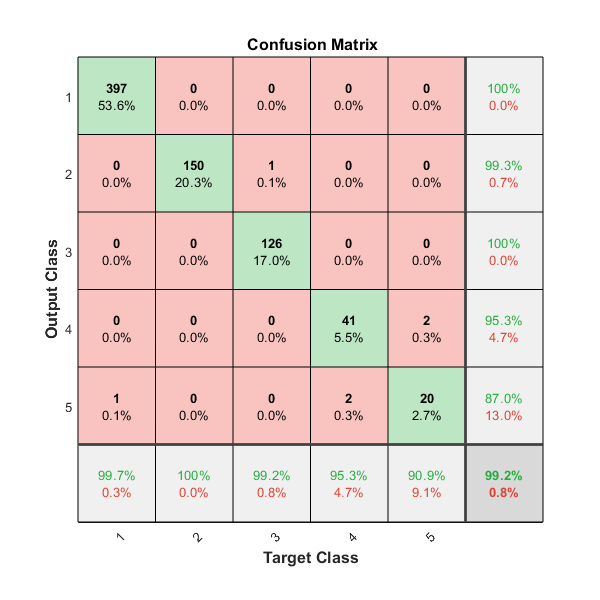

plotconfusion(cnnYtestOneHot, tstOutputsOneHot)

## 5. Compare the results of the different classification techniques using confusion matrices

Confusion matrices already generated in part 1.